## Rules of Thumb

## 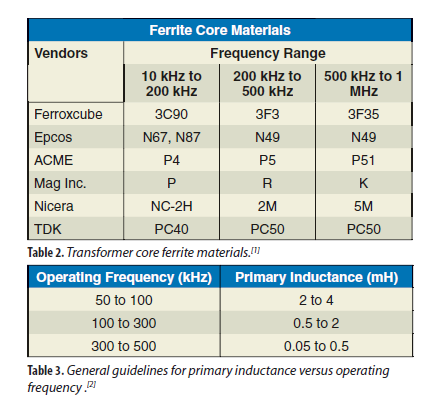

## Compute Volt-Time Product Min

Compute the minimum volt time product needed to be satisfied by the selected transformer to prevent the core flux from saturating (magnetic field can no longer increase in response to the applied voltage).


% Compute volt-time product for worst-case primary resonant frequency,
% detuned by 10 %
f_res_pri_detuned = SYSTEM.F_res_pri * 0.90;

% GDT drive signal is balanced (50 % duty cycle), therefore on-time is half
% resonant period
t_pri_max = (1/f_res_pri_detuned)*0.5;

Vt_min = V_gdt_drive * t_pri_max;   % Volt-time product, Volt*sec

fprintf("\n\n################ GDT Params BEGIN ##########################\n\n")
fprintf("Volt-time product min: %0.2f V*usec\n\n",Vt_min*1e6)
fprintf("################ GDT Params END ##########################\n\n")